clear All
clc

## Importing variety of time series

Importing S&P 500 Daily time series

spx_short = readmatrix('../data/spx_daily_11-21.csv');
spx_short = fliplr(transpose(spx_short(:,2)));
idx = 1:length(spx_short);
disp("S&P 500 Daily: (length: "+length(spx_short)+")")

S&P 500 Daily: (length: 2560)


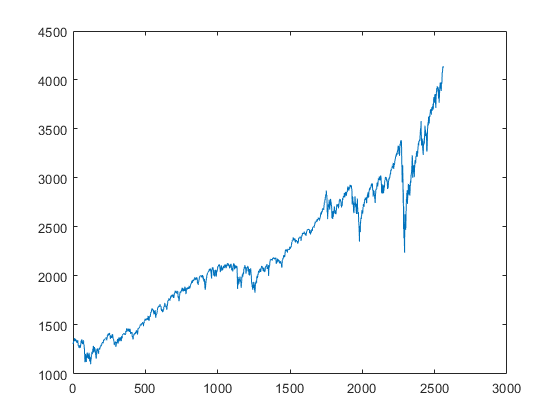

plot(idx,spx_short)

Importing S&P 500 all time Monthly time series over 200 years

spx_long = readmatrix('../data/spx_monthly_alltime.csv');
spx_long = transpose(spx_long(:,2));
idx = 1:length(spx_long);
disp("S&P 500 all time: (length: "+length(spx_long)+")")

S&P 500 all time: (length: 1768)


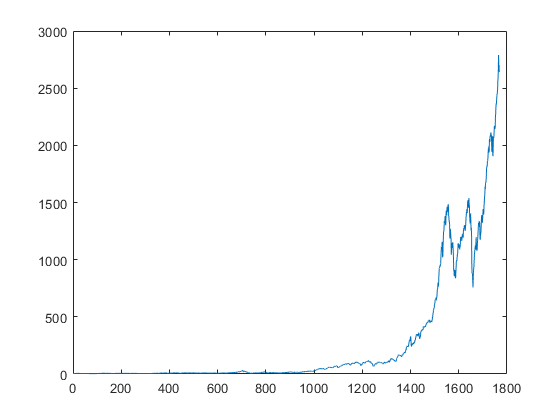

plot(idx,spx_long)

Importing minimum temperature dataset

min_daily_temp = readmatrix('../data/daily-minimum-temperatures-in-melbourne.csv');
min_daily_temp = transpose(min_daily_temp(:,2));
idx = 1:length(min_daily_temp);
disp("Minimum temperature dataset: (length: "+length(min_daily_temp)+")")

Minimum temperature dataset: (length: 3650)


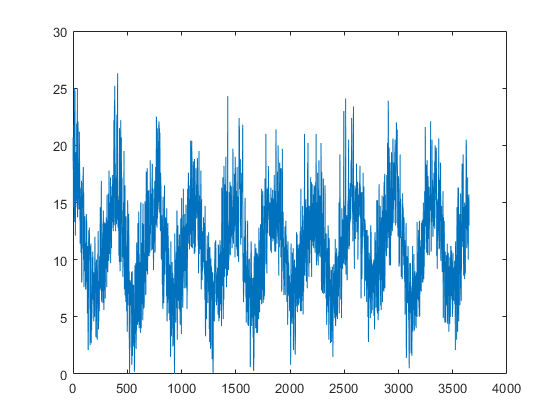

plot(idx,min_daily_temp)

Importing german GDP

bip_de = readmatrix('../data/bip_de_preisbereinigt.csv');
bip_de = transpose(bip_de(:,2));
idx = 1:length(bip_de);
disp("German GDP: (length: "+length(bip_de)+")")

German GDP: (length: 71)


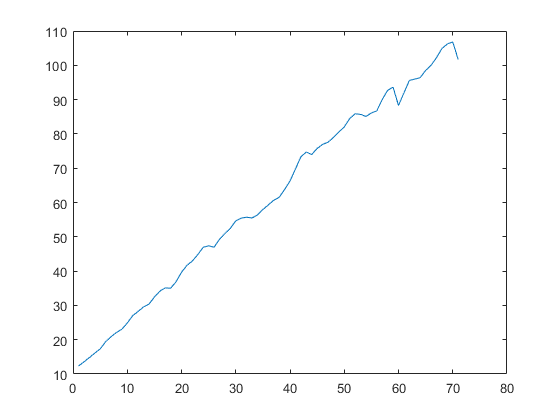

plot(idx,bip_de)

Importing german DAX 2021

dax = readmatrix('../data/dax.csv');
dax = transpose(dax(:,2));
idx = 1:length(dax);
disp("DAX 2021: (length: "+length(dax)+")")

DAX 2021: (length: 254)


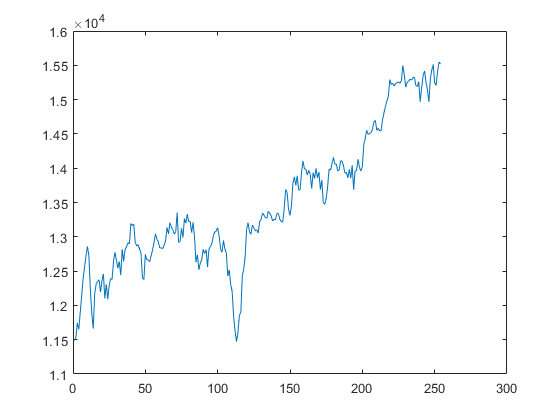

plot(idx,dax)

Importing german DAX alltime

dax_alltime = readmatrix('../data/dax_alltime.csv');
dax_alltime = transpose(dax_alltime(:,2));
for i=2:length(dax_alltime)
    if isnan(dax_alltime(i))
        dax_alltime(i) = dax_alltime(i-1);
    end
end
idx = 1:length(dax_alltime);
disp("DAX all time: (length: "+length(dax_alltime)+")")

DAX all time: (length: 8602)


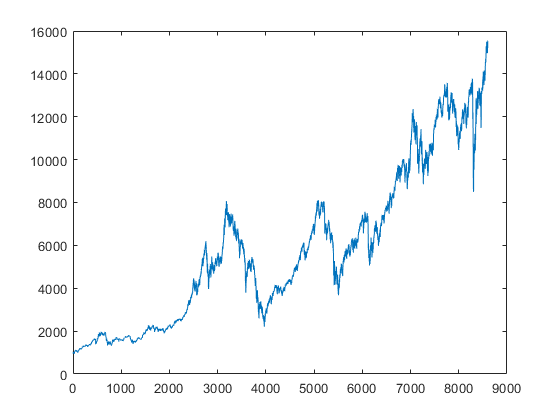

plot(idx,dax_alltime)

Importing Bitcoin alltime

bitcoin_alltime = readmatrix('../data/bitcoin_alltime.csv');
bitcoin_alltime = transpose(bitcoin_alltime(:,2));
for i=2:length(bitcoin_alltime)
    if isnan(bitcoin_alltime(i))
        bitcoin_alltime(i) = bitcoin_alltime(i-1);
    end
end
idx = 1:length(bitcoin_alltime);
disp("Bitcoin all time: (length: "+length(bitcoin_alltime)+")")

Bitcoin all time: (length: 2444)


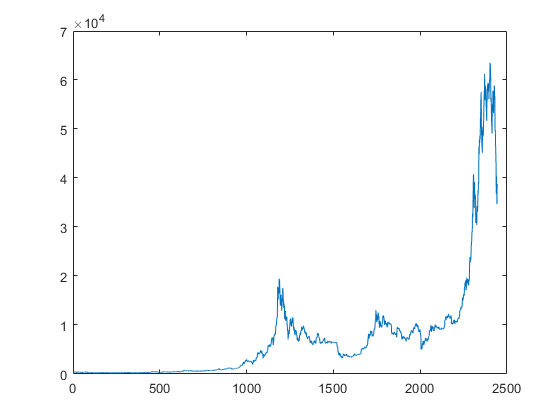

plot(idx,bitcoin_alltime)

Importing hydraulic pressure Data Set

hydraulic = readmatrix('../data/PS1.csv');
hydraulic = transpose(hydraulic(2:length(hydraulic),2));
for i=2:length(hydraulic)
    if isnan(hydraulic(i))
        hydraulic(i) = hydraulic(i-1);
    end
end
idx = 1:length(hydraulic);
disp("Hydraulic pressure data set: (length: "+length(hydraulic)+")")

Hydraulic pressure data set: (length: 6000)


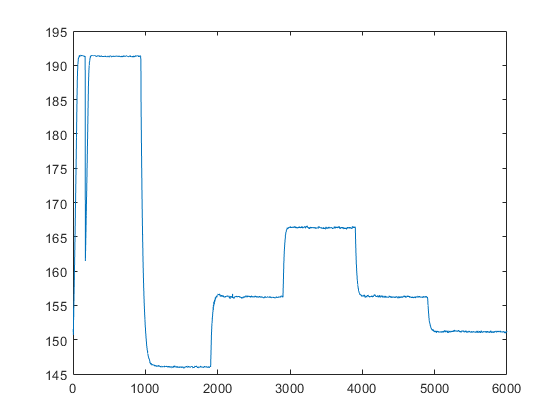

plot(idx,hydraulic)

Importing Beijing O3 in air concentration (quality)

quality = readmatrix('../data/PRSA_Data_Dingling_20130301-20170228.csv');
quality = transpose(quality(:,11));
for i=2:length(quality)
    if isnan(quality(i))
        quality(i) = quality(i-1);
    end
end
idx = 1:length(quality);
disp("Beijing O3 in air concentration : (length: "+length(quality)+")")

Beijing O3 in air concentration : (length: 35064)


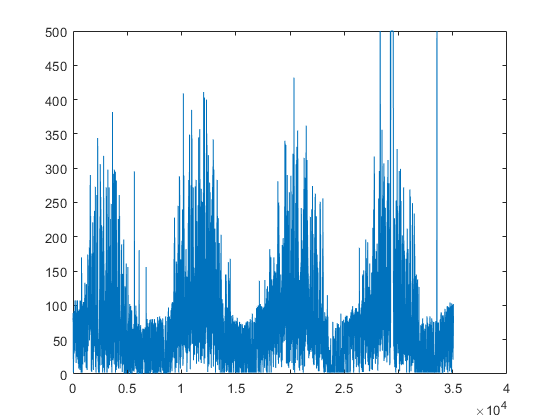

plot(idx,quality)

## Setting hyper parameters for experiment run

% number of iterations of meaningfulness calculation to average over.
n = 10;
% size of cluster set to be calculated for within/between set cluster distance.
r = 3;

ks = [3 5 7 11];
ws = [8 16 32];

normMethods = ["none" "zscore" "norm" "scale" "range" "medianiqr"];
distMetrics = ["eukl" ""];
clusterAlgos = ["kmeans" "agglo" "gmm"];
% timeSeries = [spx_short spx_long min_daily_temp dax dax_alltime bitcoin_alltime quality hydraulic]

currentNorm = normMethods(5);
% used clustering algorithm
currentClusterAlgo = clusterAlgos(1);

% used distance metric
currentDistMetric = distMetrics(1);

% reduces de sampling size of the random sampled subsequences that are used for whole clustering
% if false the random samples matrix has the same height as the sts matrix
reducedSamplingSize = true;
dimRed = true;

% if hyperparameters should be same among all cluster algorithms
unify = true;

% used time series
currentTs = spx_long;
% Instead of a random walk we could also pass any opposing time series
%opposingTs = spx_long;
opposingTs = createRandomWalk(currentTs);

## Finally calculate Meaningfulness

disp('Experiment settings:')

Experiment settings:


disp('')
fprintf("n:                                           %d",n)

n:                                           100

fprintf('r:                                           %d',r)

r:                                           3

disp('Normalizer:                                  '+currentNorm)

Normalizer:                                  range


disp('Distance metric:                             '+currentDistMetric)

Distance metric:                             eukl


disp('Clustering algorithm:                        '+currentClusterAlgo)

Clustering algorithm:                        agglo


fprintf('Reduced sampling size for whole clustering:  %d',reducedSamplingSize)

Reduced sampling size for whole clustering:  0

fprintf('PCA:                                         %d',dimRed)

PCA:                                         0

fprintf('Unify:                                       %d',unify)

Unify:                                       0


figure
title("Target time series - (length: "+length(currentTs)+")")
plot(1:length(currentTs),currentTs)

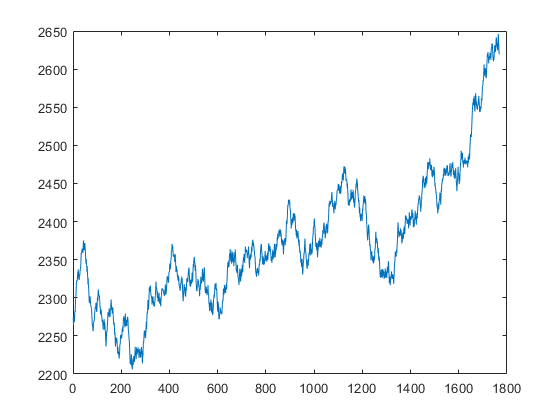

figure
title("Opposing time series - (length: "+length(opposingTs)+")")
plot(1:length(opposingTs),opposingTs)

disp("(1) Results individual:")

(1) Results individual:



meaningfulness_combined = zeros(length(ks),2);
for w = 1:length(ws)
    for k = 1:length(ks)
        m = calculateMeaningfulness(currentTs,opposingTs,n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        meaningfulness_combined(k,:,w) = round(m, 2);
        disp("w="+ws(w)+", k="+ks(k)+" -- STS-meaning: "+m(1)+", Whole-meaning: "+m(2)+"");
    end
end

w=8, k=3 -- STS-meaning: 0, Whole-meaning: 0
w=8, k=5 -- STS-meaning: 0, Whole-meaning: 0
w=8, k=7 -- STS-meaning: 0, Whole-meaning: 0
w=8, k=11 -- STS-meaning: 0, Whole-meaning: 0
w=16, k=3 -- STS-meaning: 0, Whole-meaning: 0
w=16, k=5 -- STS-meaning: 0, Whole-meaning: 0
w=16, k=7 -- STS-meaning: 0, Whole-meaning: 0
w=16, k=11 -- STS-meaning: 0, Whole-meaning: 0
w=32, k=3 -- STS-meaning: 0, Whole-meaning: 0
w=32, k=5 -- STS-meaning: 0, Whole-meaning: 0
w=32, k=7 -- STS-meaning: 0, Whole-meaning: 0
w=32, k=11 -- STS-meaning: 0, Whole-meaning: 0


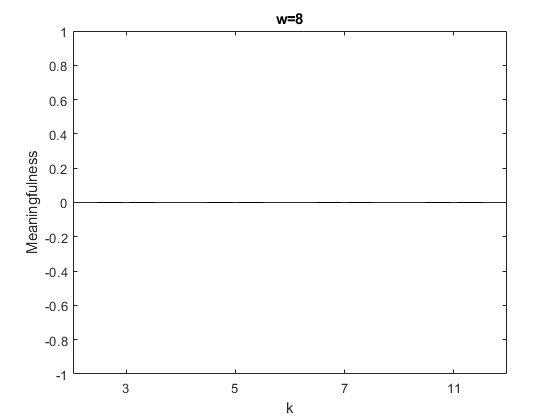

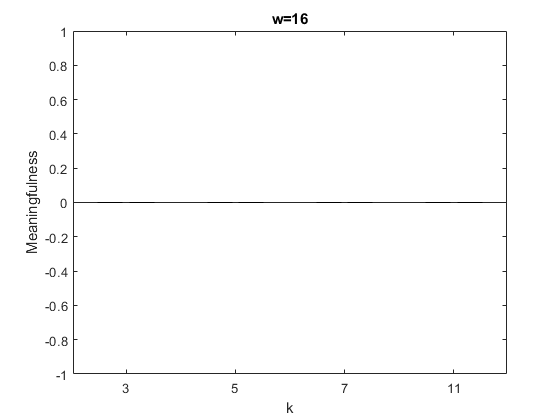

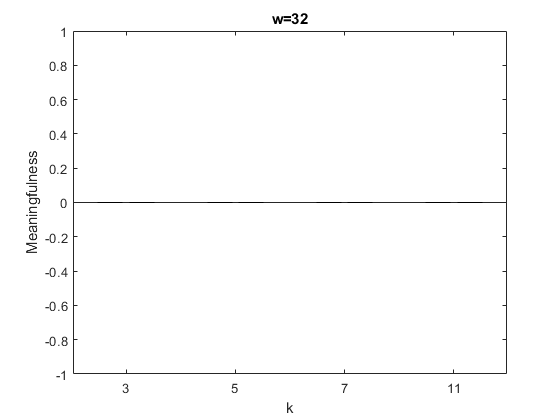


for w = 1:length(ws)
    bar(1:length(ks),meaningfulness_combined(:,:,w))
    set(gca,'XTickLabel',{'3', '5', '7', '11'})
    title("w="+ws(w))
    xlabel('k')
    ylabel('Meaningfulness')
    figure
end

disp("(2) Averaged results over all time series:")

(2) Averaged results over all time series:



n = 10;
r = 10;

ks = [3 5 7 11];
ws = [8 16 32];


meaningfulness_combined = zeros(length(ks),2);
for w = 1:length(ws)
    for k = 1:length(ks)
        m = calculateMeaningfulness(spx_short, spx_short, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: spx_short')
        m = m + calculateMeaningfulness(spx_long, spx_long, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: spx_long')
        m = m + calculateMeaningfulness(min_daily_temp, min_daily_temp, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: min_daily_temp')
        m = m + calculateMeaningfulness(dax_alltime, dax_alltime, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: dax_alltime')
        m = m + calculateMeaningfulness(bitcoin_alltime, bitcoin_alltime, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: bitcoin_alltime')
        m = m + calculateMeaningfulness(quality, quality, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: quality')
        m = m + calculateMeaningfulness(hydraulic, hydraulic, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: hydraulic')
        m = m / 7;
        meaningfulness_combined(k,:,w) = [m(1) m(2)];
            disp("w="+ws(w)+", k="+ks(k)+" -- STS-meaning: "+m(1)+", Whole-meaning: "+m(2)+"");
    end
end

for w = 1:length(ws)
    bar(1:length(ks),meaningfulness_combined(:,:,w))
    set(gca,'XTickLabel',{'3', '5', '7', '11'})
    title("w="+ws(w))
    xlabel('k')
    ylabel('Meaningfulness')
    figure
end

### Analysing centroids and meaningfulness in detail

First we analyze how the meaningfulness differs among the seven time series.

n = 3;
r = 10;

ks = [3 5 7 11];
ws = [8 16 32];


m = zeros(7,2);
for w = 1:length(ws)
    for k = 1:length(ks)
        m(1,:) = m(1,:) + calculateMeaningfulness(spx_short, spx_short, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: spx_short')
        m(2,:) = m(2,:) + calculateMeaningfulness(spx_long, spx_long, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: spx_long')
        m(3,:) = m(3,:) + calculateMeaningfulness(min_daily_temp, min_daily_temp, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: min_daily_temp')
        m(4,:) = m(4,:) + calculateMeaningfulness(dax_alltime, dax_alltime, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: dax_alltime')
        m(5,:) = m(5,:) + calculateMeaningfulness(bitcoin_alltime, bitcoin_alltime, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: bitcoin_alltime')
        m(6,:) = m(6,:) + calculateMeaningfulness(quality, quality, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: quality')
        m(7,:) = m(7,:) + calculateMeaningfulness(hydraulic, hydraulic, n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: hydraulic')
        %disp(m)
    end
end

Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    0.9143    0.5434
    0.8473    0.5618
    0.8728    0.7826
    0.9033    0.6130
    0.8656    0.7805
    0.3216    0.9609
    0.6556    0.6677



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    1.7079    1.2146
    1.8003    1.3345
    1.7261    1.4641
    1.7679    1.3437
    1.8024    1.4898
    1.0834    1.5274
    1.6018    1.4968



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    2.6533    1.9067
    2.7083    1.9812
    2.5979    2.2144
    2.5413    2.0057
    2.6021    2.1455
    2.0190    2.4054
    2.5022    2.2525



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    3.5173    2.6181
    3.5941    2.6929
    3.4149    2.9457
    3.4228    2.7490
    3.5275    2.8360
    2.8514    3.2538
    3.4348    2.9613



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    4.5059    3.1945
    4.4889    3.1505
    4.4280    3.8196
    3.7878    3.4187
    4.4066    3.4356
    3.6637    3.8593
    4.3630    3.7786



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    5.4351    3.7742
    5.1783    3.8176
    5.3305    4.5982
    4.6831    4.1344
    5.2945    4.2476
    4.5814    4.4294
    5.1477    4.5073



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    6.2615    4.3790
    6.0983    4.4531
    6.2658    5.3540
    5.6626    4.8031
    6.1349    4.9092
    5.6009    5.1055
    6.0017    5.2394



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    7.1694    5.0563
    6.9590    5.0277
    7.2217    6.0751
    6.4569    5.4043
    7.0467    5.5125
    6.3020    5.5207
    6.8923    5.9936



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    8.1435    5.6467
    7.8521    5.7014
    8.1829    6.9420
    7.4414    6.0346
    7.9169    6.0472
    7.3792    5.8769
    7.8103    6.6892



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    9.0617    6.3243
    8.7192    6.3448
    9.0788    7.7470
    8.4958    6.5886
    8.7400    6.7283
    8.1674    6.5756
    8.7769    7.3774



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


    9.9643    6.8943
    9.5375    6.9739
    9.9587    8.5251
    9.4093    7.1695
    9.7036    7.3338
    9.0423    7.3494
    9.7267    8.0715



Calculated: spx_short


Calculated: spx_long


Calculated: min_daily_temp


Calculated: dax_alltime


Calculated: bitcoin_alltime


Calculated: quality


Calculated: hydraulic


   10.8560    7.5965
   10.4594    7.6241
   10.8612    9.3090
   10.3181    7.8934
   10.5841    7.9191
    9.9141    7.9461
   10.6053    8.7514



m = round((m / 12),2);
disp(m)

    0.9000    0.6300
    0.8700    0.6400
    0.9100    0.7800
    0.8600    0.6600
    0.8800    0.6600
    0.8300    0.6600
    0.8800    0.7300

